# Ejemplo ANOVA Una-vía

Load the  iris data set.  

`X` is a numeric matrix that contains four petal measurements for 150 irises. 

`Y` is a cell array of character vectors that contains the corresponding iris species: setosa, versicolor, virginica

Characteristics (cm): Sepal length, Sepal width, Petal length, Petal width

clearvars;
% load fisheriris
meas = csvread('../Dataset/Train_Input.csv');
species = csvread('../Dataset/Train_Targets.csv');
X = meas;
Y = species;

NC1=100; NC2=100; NC3=100; % data set size for each class. 4 characteristics (Sepal len
k=3; % Number of classes

**Obtain the characteristics 1 (Sepal length) of data set for each class**

Xcs1=X(1:100, 1);
Xcs2=X(101:200, 1);
Xcs3=X(201:300, 1);

**To apply the ANOVA for the feature 1 (Sepal length) **

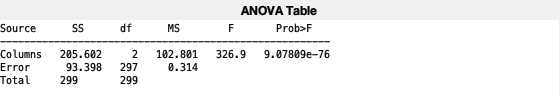

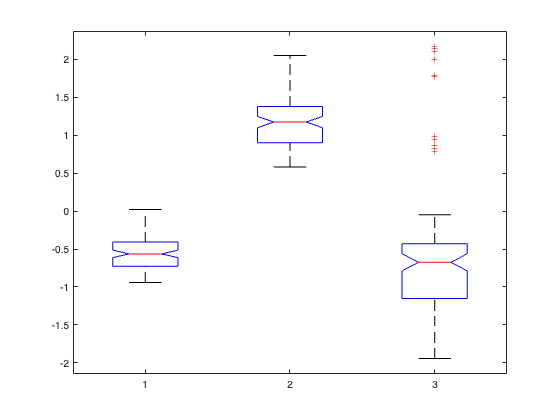

pch1 = 9.0781e-76

Ch1=[Xcs1  Xcs2  Xcs3];

pch1 = anova1(Ch1)

**Significance Level **

dat= inputdlg({'Significance level'},'Lillietest',1,{'0.01'});
Signif_Level=str2num(dat{1}); % 

**Significance level comparation**


if (pch1> Signif_Level)
    messag= ['NO statistically significant differences were detected'];
   
else 
    messag= ['YES statistically significant differences were detected'];
end   
msgbox(messag,'Mascara azul');  

**Obtain the characteristics 2 (Sepal length) of data set for each class**

Xcs1=X(1:100, 2);
Xcs2=X(101:200, 2);
Xcs3=X(201:300, 2);

**To apply the ANOVA for the feature 2 (Sepal width) **

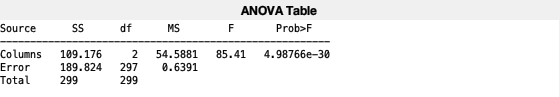

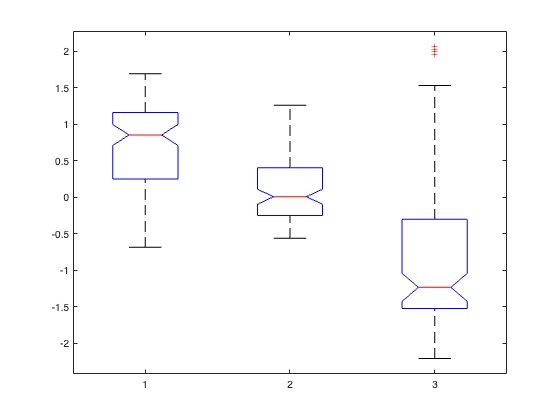

pch2 = 4.9877e-30

Ch2=[Xcs1  Xcs2  Xcs3];

pch2 = anova1(Ch2)


if (pch2> Signif_Level)
    messag= ['NO statistically significant differences were detected'];
   
else 
    messag= ['YES statistically significant differences were detected'];
end   
msgbox(messag,'Mascara verde'); 


**Obtain the characteristics 3 (Petal length) of data set for each class**

Xcs1=X(1:100, 3);
Xcs2=X(101:200, 3);
Xcs3=X(201:300, 3);

**To apply the ANOVA for the feature 3 (Petal length)** 

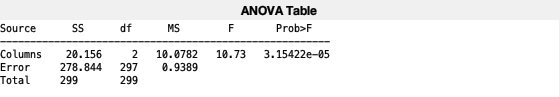

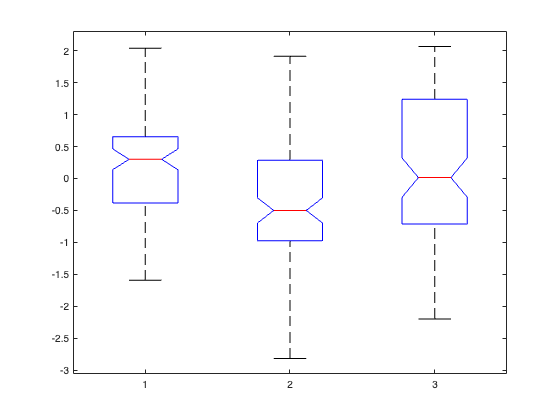

pch3 = 3.1542e-05

Ch3=[Xcs1  Xcs2  Xcs3];

pch3 = anova1(Ch3)


if (pch3> Signif_Level)
    messag= ['NO statistically significant differences were detected'];
   
else 
    messag= ['YES statistically significant differences were detected'];
end   
msgbox(messag,'Mascara rojo'); 


**Obtain the characteristics 4 (Petal length) of data set for each class**

% Xcs1=X(1:100, 4);
% Xcs2=X(101:200, 4);
% Xcs3=X(201:300, 4);

**To apply the ANOVA for the feature 4 (Petal width) **

% Ch4=[Xcs1  Xcs2  Xcs3];
% 
% pch4 = anova1(Ch4)
% 
% if (pch4> Signif_Level)
%     messag= ['NO statistically significant differences were detected'];
% 
% else 
%     messag= ['YES statistically significant differences were detected'];
% end   
% msgbox(messag,'ANOVA 1 - Charac 4'); 



Prueba: función Violin Plot

% 
% violin(Ch4,'facecolor',[1 1 0;0 1 0;.3 .3 .3;0 0.3 0.1],'edgecolor','none','bw',0.1,'mc','k','medc','r-.')
% ylabel('Petal  width','FontSize',14)


Prueba: función al_goodplot.m

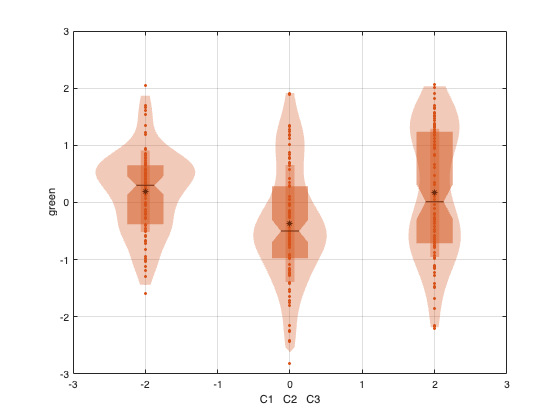

al_goodplot(Ch3,[-2 0 2]); xlabel('C1   C2   C3'); ylabel('green') 